clc;clear;close all;
syms t theta(t) g L T m x1(t) x2(t) u(t)
Eq=diff(theta,2)-g/L*sin(theta)==T/m

$$Eq(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-\frac{g\,\sin\left(\theta \left(t\right)\right)}{L}=\frac{T}{m}$$

## A

Simplified_Eq=diff(theta,2)-g/L*theta==T/m

$$Simplified\_Eq(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-\frac{g\,\theta \left(t\right)}{L}=\frac{T}{m}$$


x1==theta

$$ans(t) = x_{1}\left(t\right)=\theta \left(t\right)$$

x2==diff(theta,1)

$$ans(t) = x_{2}\left(t\right)=\frac{\partial }{\partial t}\theta \left(t\right)$$

u==T

$$ans(t) = u\left(t\right)=T$$

X(t)=[x1 x2].'

$$X(t) = \left(\begin{array}{c} x_{1}\left(t\right)\\ x_{2}\left(t\right) \end{array}\right)$$

diff(X,1)==[0 1;g/L 0]*X+[0;1/m]*u

$$ans(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=\frac{u\left(t\right)}{m}+\frac{g\,x_{1}\left(t\right)}{L} \end{array}\right)$$

## B

syms t_f
H=[10 0;0 0]

H =     10     0
     0     0


Q=[1 0;0 2]

Q =      1     0
     0     2


R=1

R = 1

J=0.5*X(t_f).'*H*X(t_f)+0.5*int(X.'*Q*X+R*u^2,[0 t_f])

$$J = 5\,{x_{1}\left(t_{f}\right)}^{2}+0.5000\,\int_{0}^{t_{f}}\left({u\left(t\right)}^{2}+{x_{1}\left(t\right)}^{2}+2\,{x_{2}\left(t\right)}^{2}\right)\mathrm{d}t$$

t_f=10

t_f = 10

dt=0.02;
N=t_f/dt

N = 500

syms k
g=9.8

g = 9.8000

L=0.5

L = 0.5000

m=1

m = 1

X(k+1)==(eye(2)+dt*[0 1;g/L 0])*X(k)+dt*[0;1/m]*u(k)

$$ans = \left(\begin{array}{c} x_{1}\left(k+1\right)=x_{1}\left(k\right)+0.0200\,x_{2}\left(k\right)\\ x_{2}\left(k+1\right)=0.0200\,u\left(k\right)+0.3920\,x_{1}\left(k\right)+x_{2}\left(k\right) \end{array}\right)$$

J=0.5*X(N).'*H*X(N)+0.5*symsum(X(k).'*Q*X(k)+R*u(k)^2,k)

$$J = 0.5000\,\left(\sum_{k}\left({u\left(k\right)}^{2}+{x_{1}\left(k\right)}^{2}+2\,{x_{2}\left(k\right)}^{2}\right)\right)+5\,{x_{1}\left(500\right)}^{2}$$

syms F [1 2] 
U_star=F*X

$$U\_star(t) = F_{1}\,x_{1}\left(t\right)+F_{2}\,x_{2}\left(t\right)$$

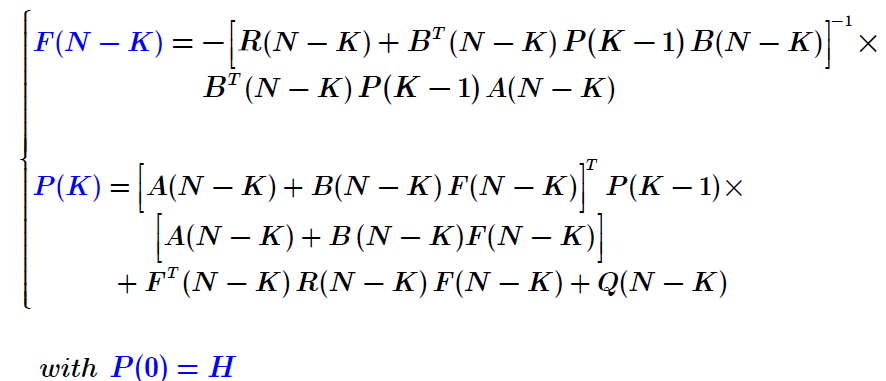



X0=[0 10]'*pi/180

X0 =          0
    0.1745


## C

A=[0 1;g/L 0];
B=[0;1/m];
Ak=eye(2)+dt*[0 1;g/L 0]

Ak =     1.0000    0.0200
    0.3920    1.0000


Bk=dt*[0;1/m]

Bk =          0
    0.0200


P0=H

P0 =     10     0
     0     0


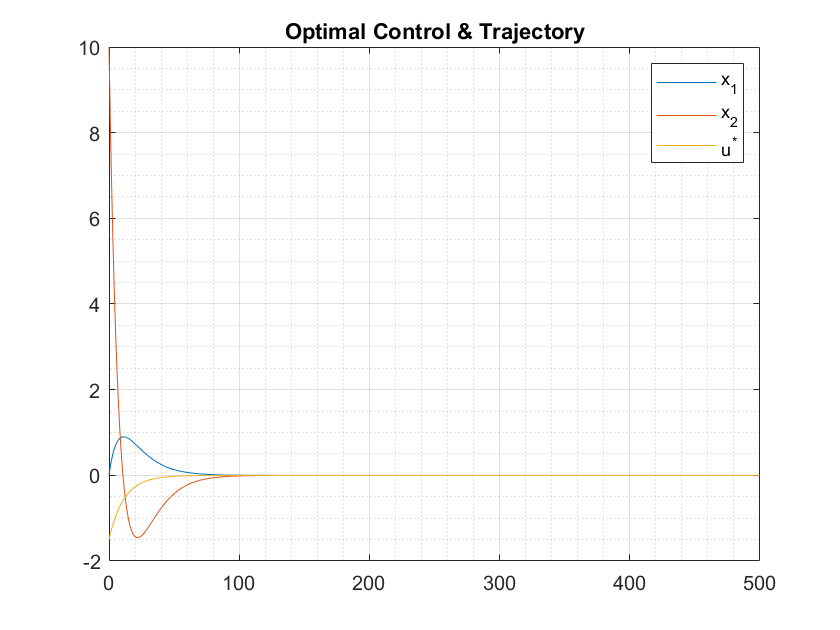

F=zeros(1,2,N);
P=zeros(2,2,N+1);
X=zeros(2,1,N+1);
U=zeros(1,1,N);
P(:,:,1)=P0;
X(:,:,1)=X0;
for k=1:N
    F(:,:,N+1-k)=-((R+Bk'*P(:,:,k)*Bk)^-1)*Bk'*P(:,:,k)*Ak;
    P(:,:,k+1)=(Ak+Bk*F(:,:,N+1-k))'*P(:,:,k)*(Ak+Bk*F(:,:,N+1-k))+F(:,:,N+1-k)'*R*F(:,:,N+1-k)+Q;
end

for k=1:N
    U(:,:,k)=F(:,:,k)*X(:,:,k);
    X(:,:,k+1)=(Ak)*X(:,:,k)+Bk*U(:,:,k);
end
X1=reshape(X(1,1,:),[1,N+1])*180/pi;
figure
plot((0:N),X1)
hold on
X2=reshape(X(2,1,:),[1,N+1])*180/pi;
plot((0:N),X2)
grid on
grid minor
U_s=reshape(U(1,1,:),[1,N]);
plot((0:N-1),U_s)
title('Optimal Control & Trajectory')
legend('x_1','x_2','u^*')


%a)
R=0.01

R = 0.0100

t_f=10

t_f = 10

dt=0.02;
N=t_f/dt

N = 500

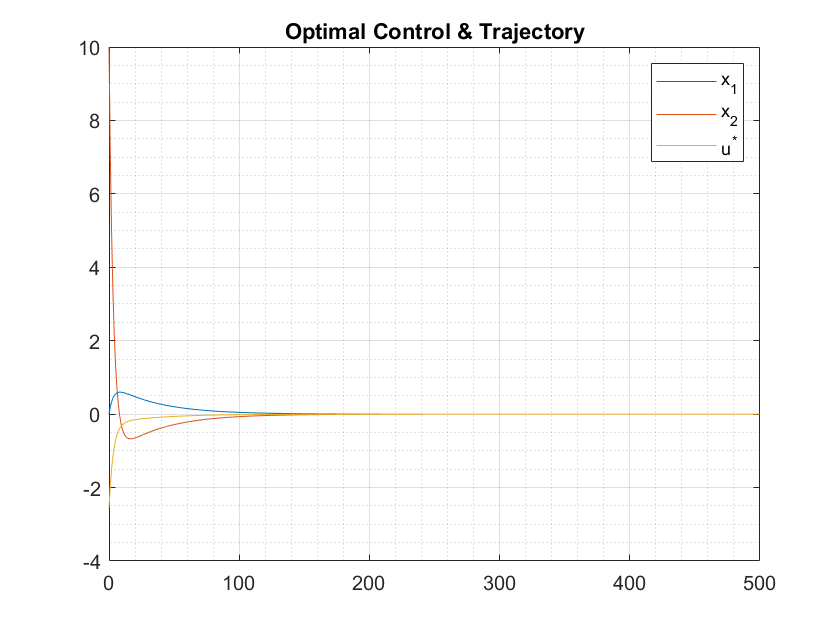

F=zeros(1,2,N);
P=zeros(2,2,N+1);
X=zeros(2,1,N+1);
U=zeros(1,1,N);
P(:,:,1)=P0;
X(:,:,1)=X0;
for k=1:N
    F(:,:,N+1-k)=-((R+Bk'*P(:,:,k)*Bk)^-1)*Bk'*P(:,:,k)*Ak;
    P(:,:,k+1)=(Ak+Bk*F(:,:,N+1-k))'*P(:,:,k)*(Ak+Bk*F(:,:,N+1-k))+F(:,:,N+1-k)'*R*F(:,:,N+1-k)+Q;
end

for k=1:N
    U(:,:,k)=F(:,:,k)*X(:,:,k);
    X(:,:,k+1)=(Ak)*X(:,:,k)+Bk*U(:,:,k);
end
X1=reshape(X(1,1,:),[1,N+1])*180/pi;
figure
plot((0:N),X1)
hold on
X2=reshape(X(2,1,:),[1,N+1])*180/pi;
plot((0:N),X2)
grid on
grid minor
U_s=reshape(U(1,1,:),[1,N]);
plot((0:N-1),U_s)
title('Optimal Control & Trajectory')
legend('x_1','x_2','u^*')

X1a=X1;
X2a=X2;
Ua=U_s;

%b)
R=100

R = 100

t_f=1

t_f = 1

dt=0.02;
N=t_f/dt

N = 50

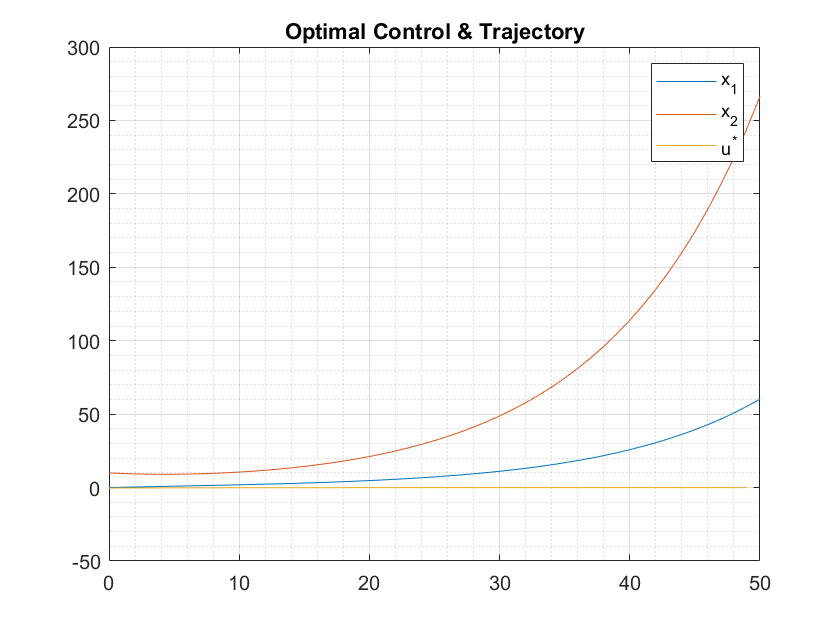

F=zeros(1,2,N);
P=zeros(2,2,N+1);
X=zeros(2,1,N+1);
U=zeros(1,1,N);
P(:,:,1)=P0;
X(:,:,1)=X0;
for k=1:N
    F(:,:,N+1-k)=-((R+Bk'*P(:,:,k)*Bk)^-1)*Bk'*P(:,:,k)*Ak;
    P(:,:,k+1)=(Ak+Bk*F(:,:,N+1-k))'*P(:,:,k)*(Ak+Bk*F(:,:,N+1-k))+F(:,:,N+1-k)'*R*F(:,:,N+1-k)+Q;
end

for k=1:N
    U(:,:,k)=F(:,:,k)*X(:,:,k);
    X(:,:,k+1)=(Ak)*X(:,:,k)+Bk*U(:,:,k);
end
X1=reshape(X(1,1,:),[1,N+1])*180/pi;
figure
plot((0:N),X1)
hold on
X2=reshape(X(2,1,:),[1,N+1])*180/pi;
plot((0:N),X2)
grid on
grid minor
U_s=reshape(U(1,1,:),[1,N]);
plot((0:N-1),U_s)
title('Optimal Control & Trajectory')
legend('x_1','x_2','u^*')

X1b=X1;
X2b=X2;
Ub=U_s;

## D

syms t k1(t) k2(t) k3(t)
K(t)=[k1 k2;k2 k3]

$$K(t) = \left(\begin{array}{cc} k_{1}\left(t\right) & k_{2}\left(t\right)\\ k_{2}\left(t\right) & k_{3}\left(t\right) \end{array}\right)$$

syms R
diff(K)==-(A.'*K + K*A - K*B*R^-1*B.'*K + Q)

$$ans(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}k_{1}\left(t\right)=\frac{{k_{2}\left(t\right)}^{2}}{R}-39.2000\,k_{2}\left(t\right)-1 & \frac{\partial }{\partial t}k_{2}\left(t\right)=\frac{k_{2}\left(t\right)\,k_{3}\left(t\right)}{R}-19.6000\,k_{3}\left(t\right)-k_{1}\left(t\right)\\ \frac{\partial }{\partial t}k_{2}\left(t\right)=\frac{k_{2}\left(t\right)\,k_{3}\left(t\right)}{R}-19.6000\,k_{3}\left(t\right)-k_{1}\left(t\right) & \frac{\partial }{\partial t}k_{3}\left(t\right)=\frac{{k_{3}\left(t\right)}^{2}}{R}-2\,k_{2}\left(t\right)-2 \end{array}\right)$$

EQ={diff(K)==-(A.'*K + K*A - K*B*R^-1*B.'*K + Q)};
EQ=cell2sym(EQ);
EQ=EQ([1 2 4]).'

$$EQ = \left(\begin{array}{c} \frac{\partial }{\partial t}k_{1}\left(t\right)=\frac{{k_{2}\left(t\right)}^{2}}{R}-39.2000\,k_{2}\left(t\right)-1\\ \frac{\partial }{\partial t}k_{2}\left(t\right)=\frac{k_{2}\left(t\right)\,k_{3}\left(t\right)}{R}-19.6000\,k_{3}\left(t\right)-k_{1}\left(t\right)\\ \frac{\partial }{\partial t}k_{3}\left(t\right)=\frac{{k_{3}\left(t\right)}^{2}}{R}-2\,k_{2}\left(t\right)-2 \end{array}\right)$$


% a)
X0=H

X0 =     10     0
     0     0


R=0.01

R = 0.0100

t_f=10

t_f = 10

dt=0.02

dt = 0.0200

N=t_f/dt

N = 500

[T, Xx] = ode45(@(t,X)mRiccati(t, X, A, B, Q,R), [t_f 0], X0);
T=T(end:-1:1);
X0=[0 10]'*pi/180

X0 =          0
    0.1745


K=icare(A,B,Q,R)

K =     3.7029    0.4160
    0.4160    0.1683


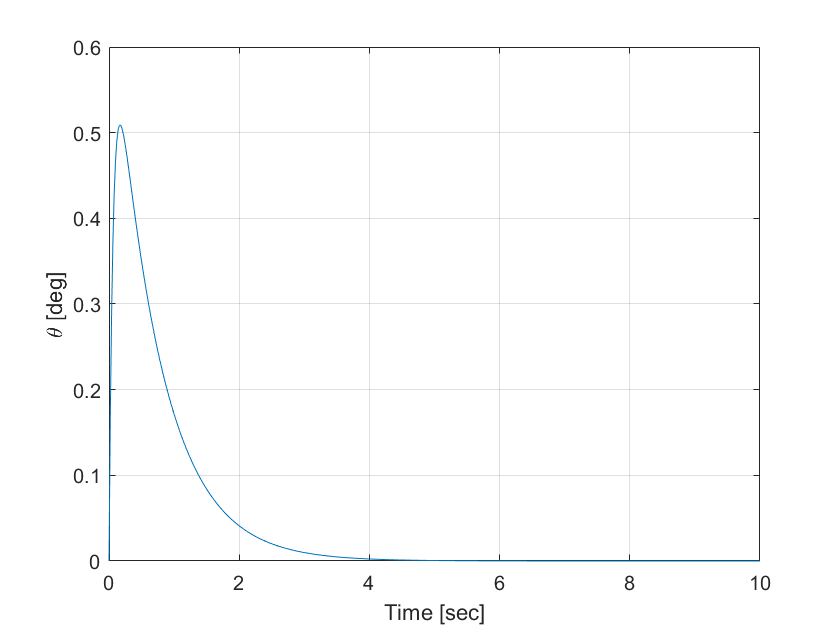

sim('C_Sim.slx');
X_a=X;
U_a=U;
figure
plot(X_a.time,X_a.signals.values(:,1)*180/pi)
grid on
ylabel('{\theta} [deg]')
xlabel('Time [sec]')

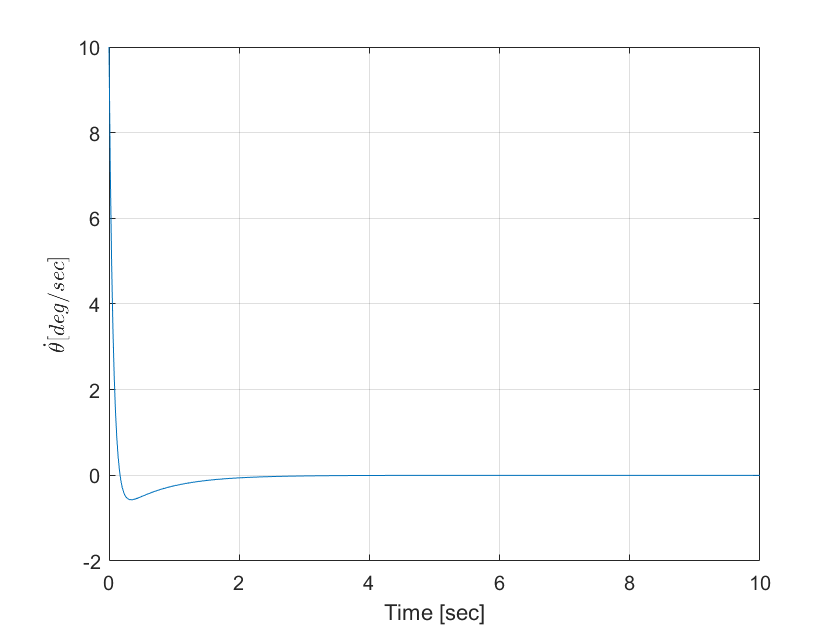


figure
plot(X_a.time,X_a.signals.values(:,2)*180/pi)
grid on
ylabel('$\dot{\theta } [deg/sec]$', 'Interpreter','latex')
xlabel('Time [sec]')

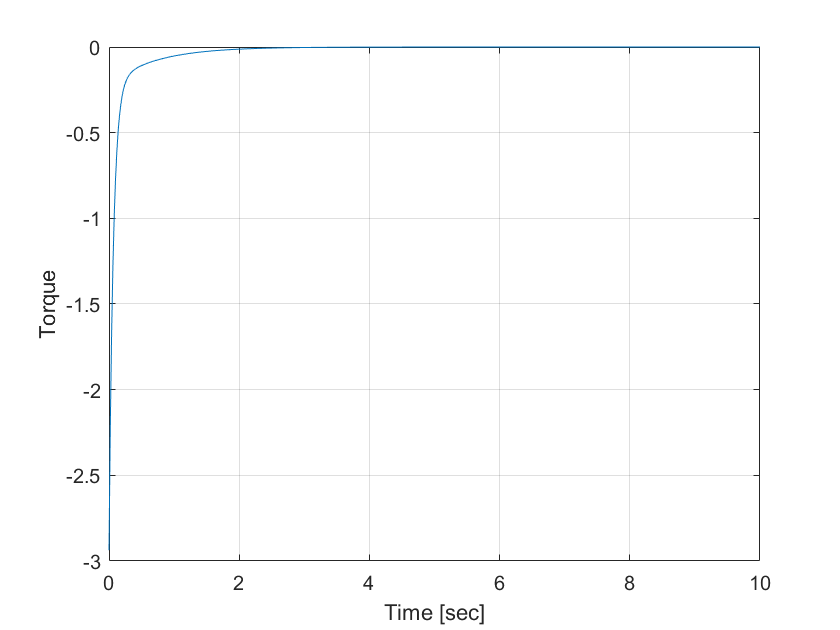


figure
plot(U_a.time,U_a.signals.values(:,1))
grid on
ylabel('Torque')
xlabel('Time [sec]')

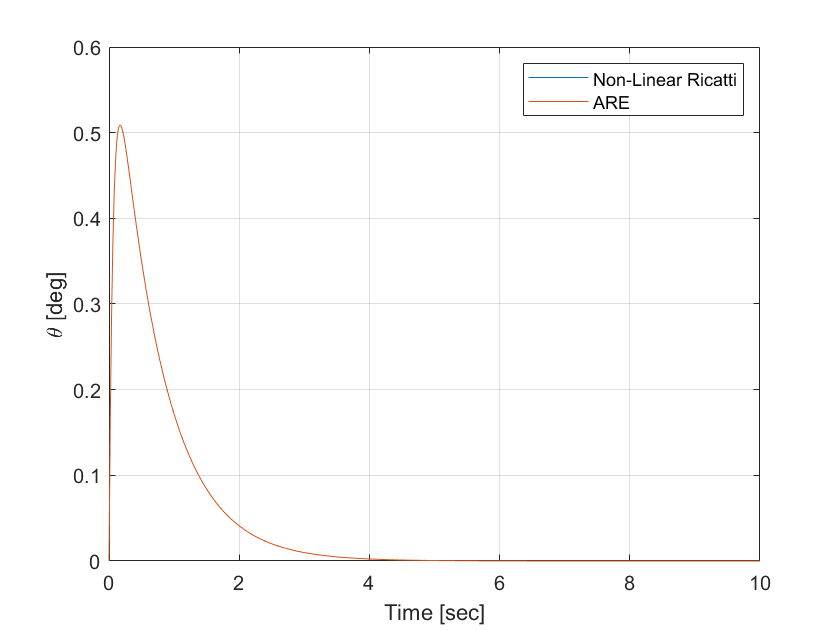


X_a1=X1;
U_a1=U1;
figure
plot(X_a.time,X_a.signals.values(:,1)*180/pi)
grid on
ylabel('{\theta} [deg]')
xlabel('Time [sec]')
hold on
plot(X_a1.time,X_a1.signals.values(:,1)*180/pi)
legend('Non-Linear Ricatti','ARE')

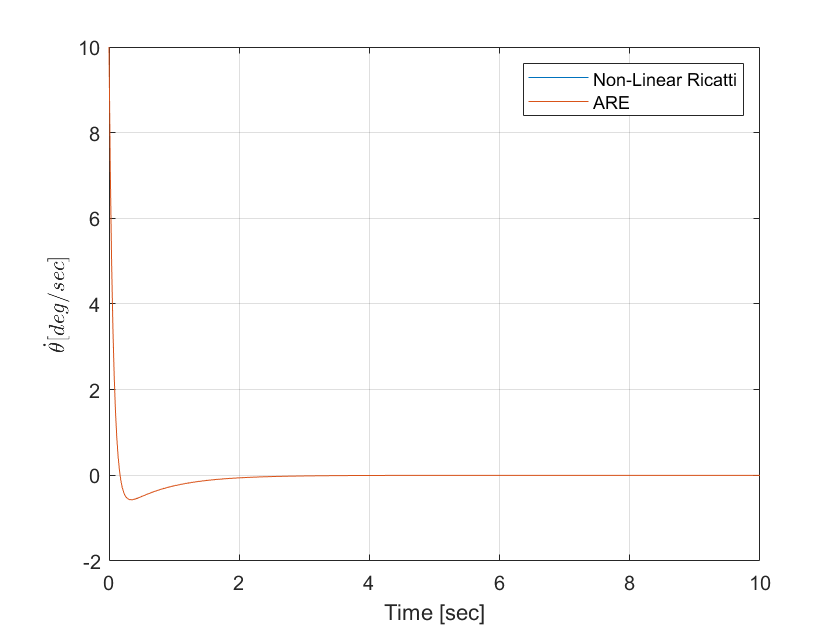


figure
plot(X_a.time,X_a.signals.values(:,2)*180/pi)
grid on
ylabel('$\dot{\theta } [deg/sec]$', 'Interpreter','latex')
xlabel('Time [sec]')
hold on
plot(X_a1.time,X_a1.signals.values(:,2)*180/pi)
legend('Non-Linear Ricatti','ARE')

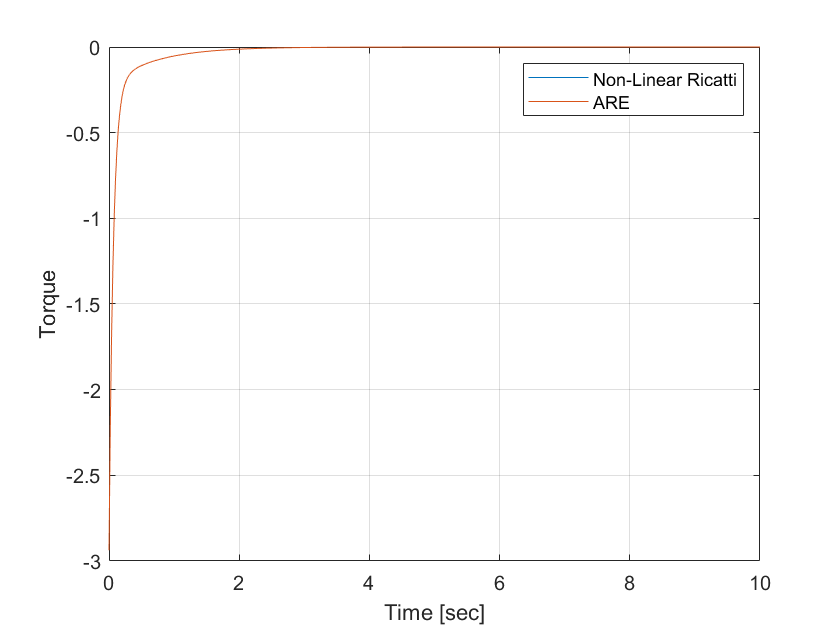


figure
plot(U_a.time,U_a.signals.values(:,1))
grid on
ylabel('Torque')
xlabel('Time [sec]')
hold on
plot(U_a1.time,U_a1.signals.values(:,1))
legend('Non-Linear Ricatti','ARE')




% b)
X0=H

X0 =     10     0
     0     0


R=100

R = 100

t_f=1

t_f = 1

dt=0.02

dt = 0.0200

N=t_f/dt

N = 50

[T, Xx] = ode45(@(t,X)mRiccati(t, X, A, B, Q,R), [t_f 0], X0);
T=T(end:-1:1);
X0=[0 10]'*pi/180

X0 =          0
    0.1745


K=icare(A,B,Q,R)

K = 	1.0e+04 *

    1.7357    0.3920
    0.3920    0.0886


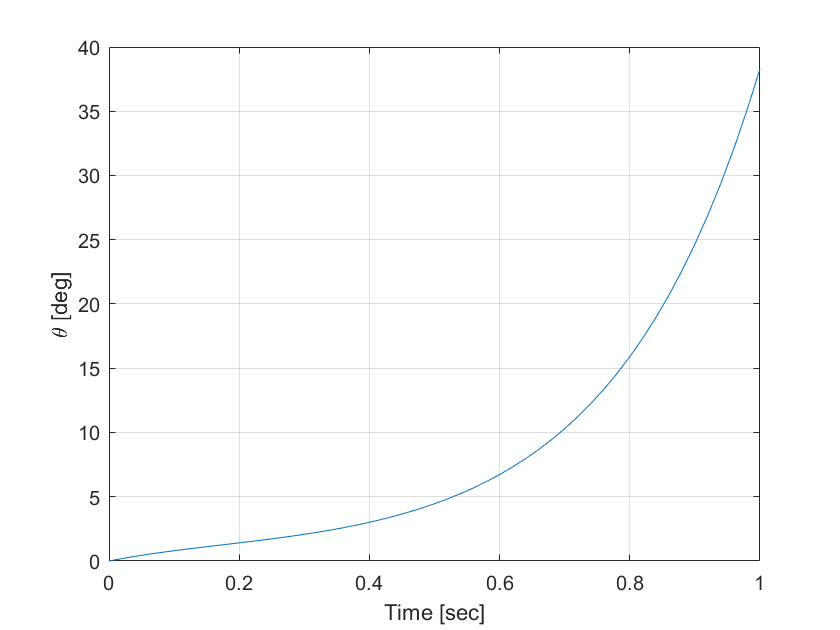

sim('C_Sim.slx');
X_b=X;
U_b=U;
figure
plot(X_b.time,X_b.signals.values(:,1)*180/pi)
grid on
ylabel('{\theta} [deg]')
xlabel('Time [sec]')

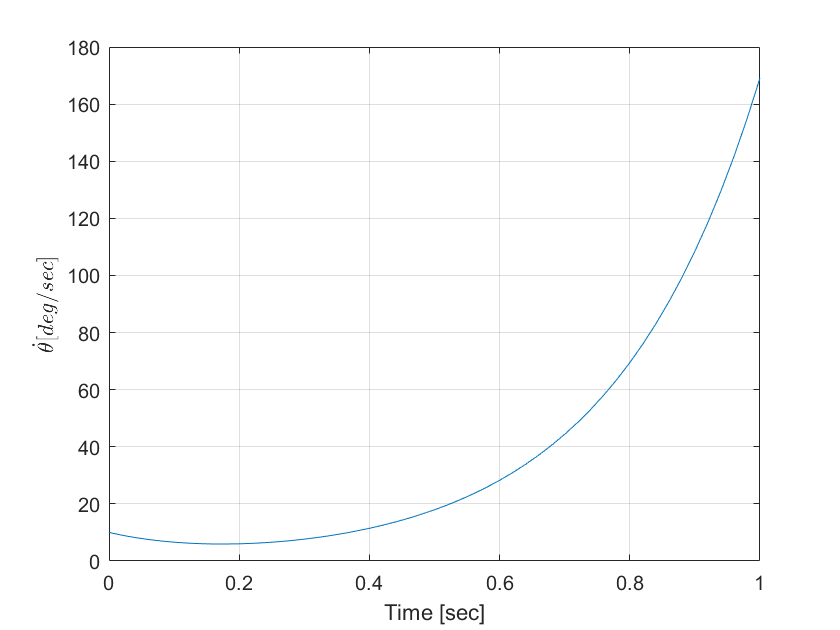


figure
plot(X_b.time,X_b.signals.values(:,2)*180/pi)
grid on
ylabel('$\dot{\theta } [deg/sec]$', 'Interpreter','latex')
xlabel('Time [sec]')

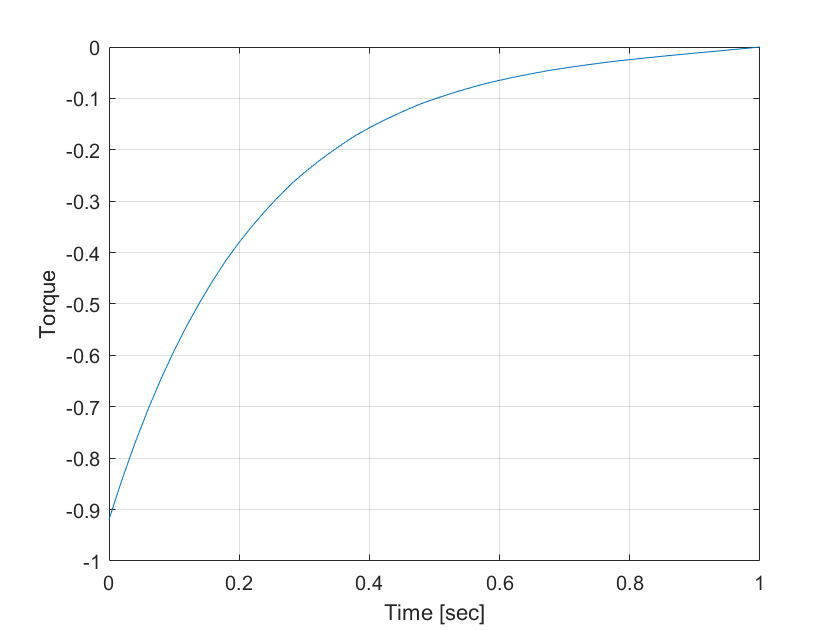


figure
plot(U_b.time,U_b.signals.values(:,1))
grid on
ylabel('Torque')
xlabel('Time [sec]')

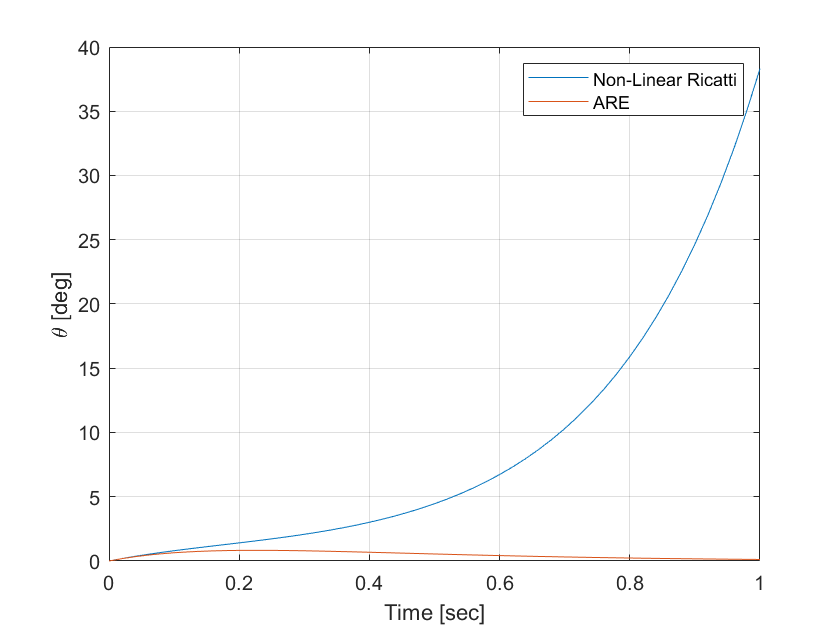


X_b1=X1;
U_b1=U1;
figure
plot(X_b.time,X_b.signals.values(:,1)*180/pi)
grid on
ylabel('{\theta} [deg]')
xlabel('Time [sec]')
hold on
plot(X_b1.time,X_b1.signals.values(:,1)*180/pi)
legend('Non-Linear Ricatti','ARE')

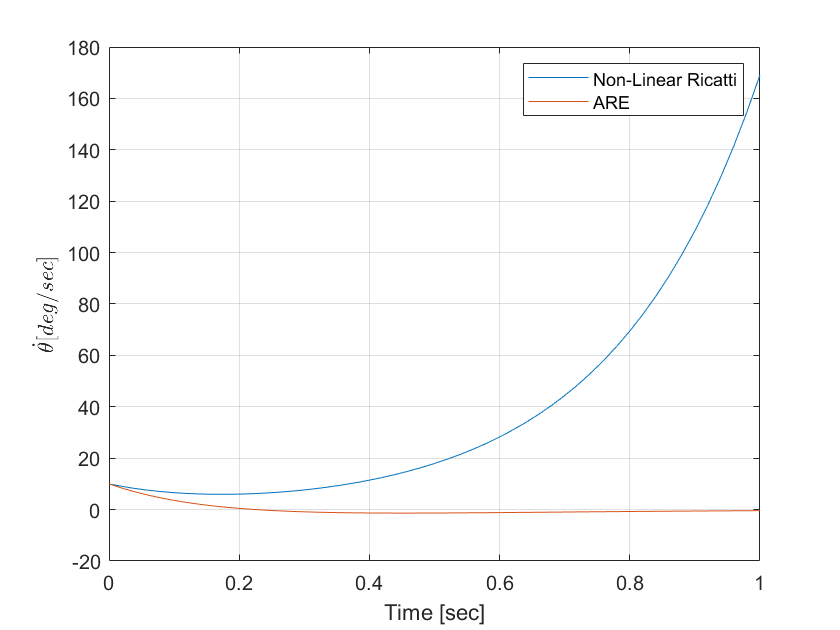


figure
plot(X_b.time,X_b.signals.values(:,2)*180/pi)
grid on
ylabel('$\dot{\theta } [deg/sec]$', 'Interpreter','latex')
xlabel('Time [sec]')
hold on
plot(X_b1.time,X_b1.signals.values(:,2)*180/pi)
legend('Non-Linear Ricatti','ARE')

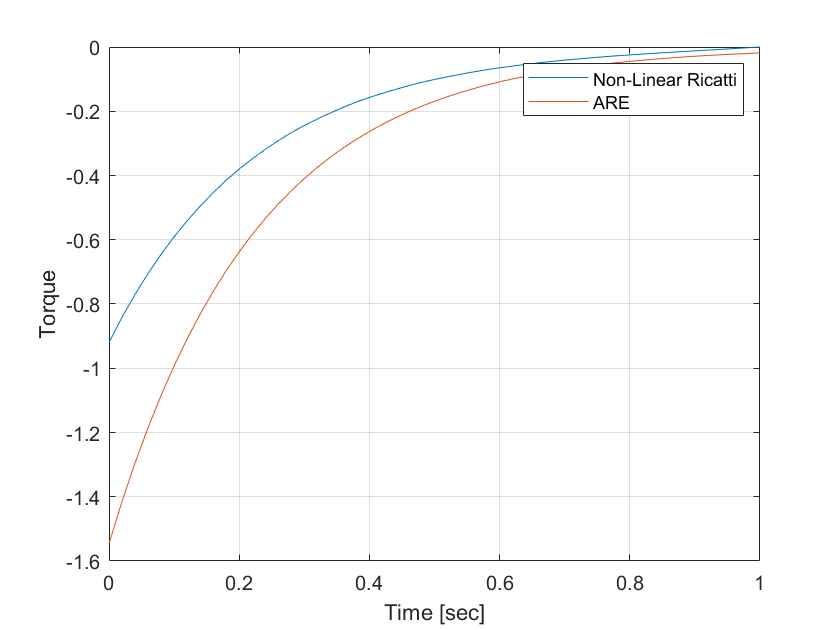


figure
plot(U_b.time,U_b.signals.values(:,1))
grid on
ylabel('Torque')
xlabel('Time [sec]')
hold on
plot(U_b1.time,U_b1.signals.values(:,1))
legend('Non-Linear Ricatti','ARE')

## E

% a)
t_f=10

t_f = 10

dt=0.02

dt = 0.0200

N=t_f/dt

N = 500

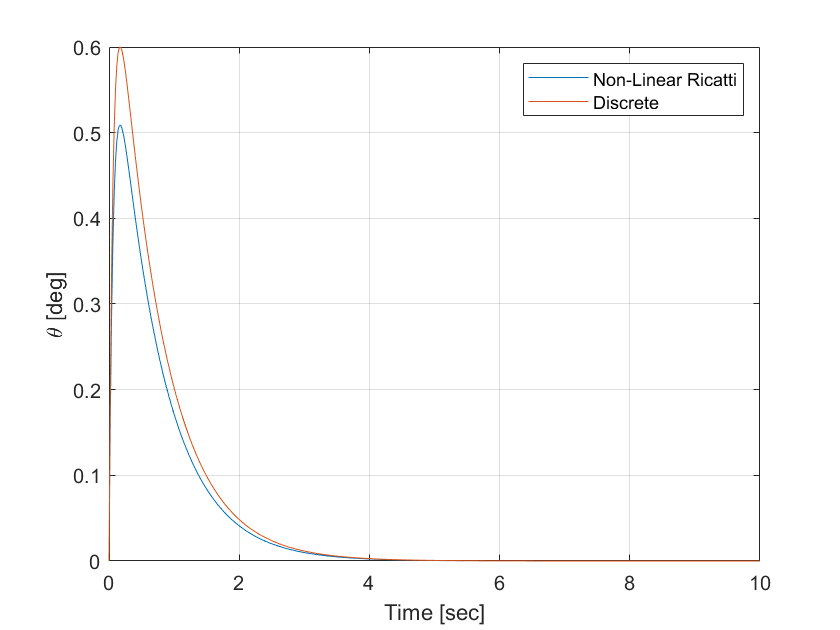

figure
plot(X_a.time,X_a.signals.values(:,1)*180/pi)
grid on
ylabel('{\theta} [deg]')
xlabel('Time [sec]')
hold on
plot((0:N)*dt,X1a)
legend('Non-Linear Ricatti','Discrete')

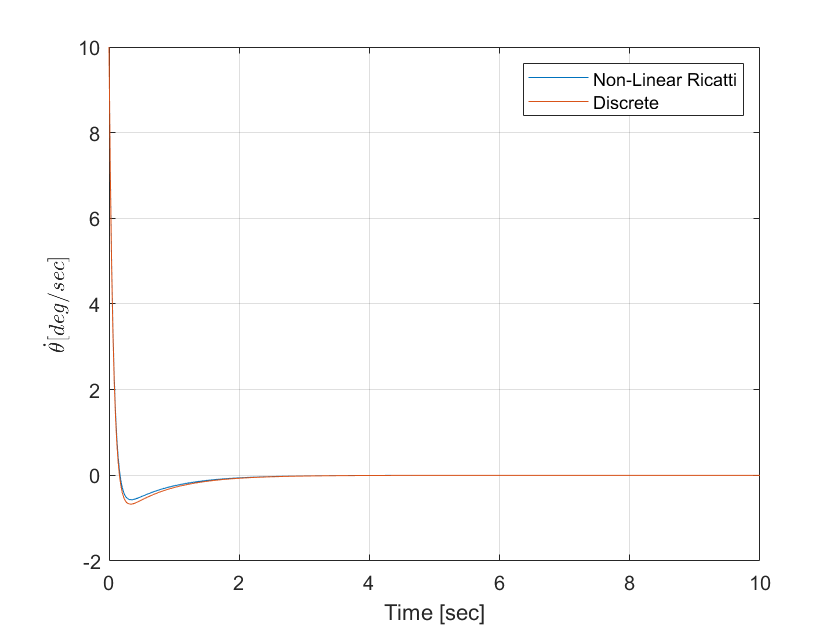

figure
plot(X_a.time,X_a.signals.values(:,2)*180/pi)
grid on
ylabel('$\dot{\theta } [deg/sec]$', 'Interpreter','latex')
xlabel('Time [sec]')
hold on
plot((0:N)*dt,X2a)
legend('Non-Linear Ricatti','Discrete')

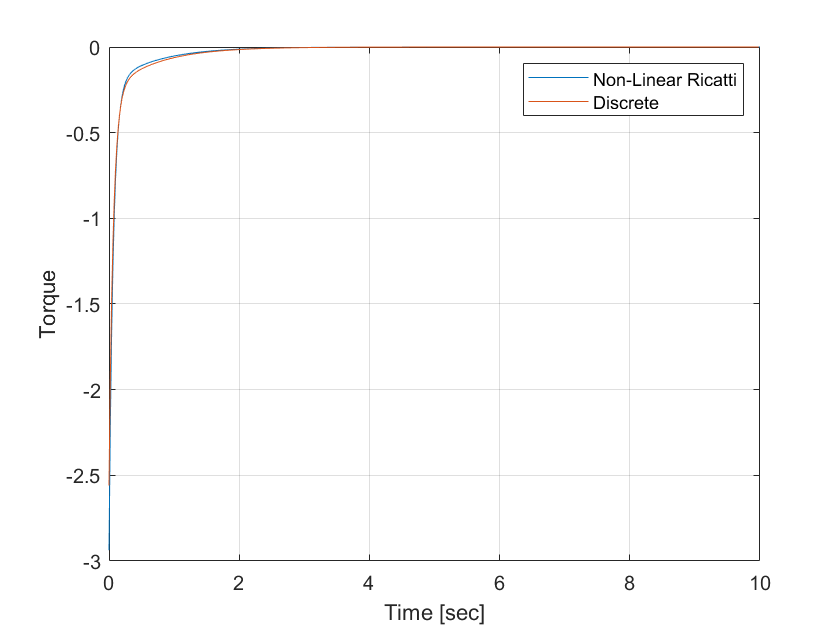


figure
plot(U_a.time,U_a.signals.values(:,1))
grid on
ylabel('Torque')
xlabel('Time [sec]')
hold on
plot((0:N-1)*dt,Ua)
legend('Non-Linear Ricatti','Discrete')


% b)
t_f=1

t_f = 1

dt=0.02

dt = 0.0200

N=t_f/dt

N = 50

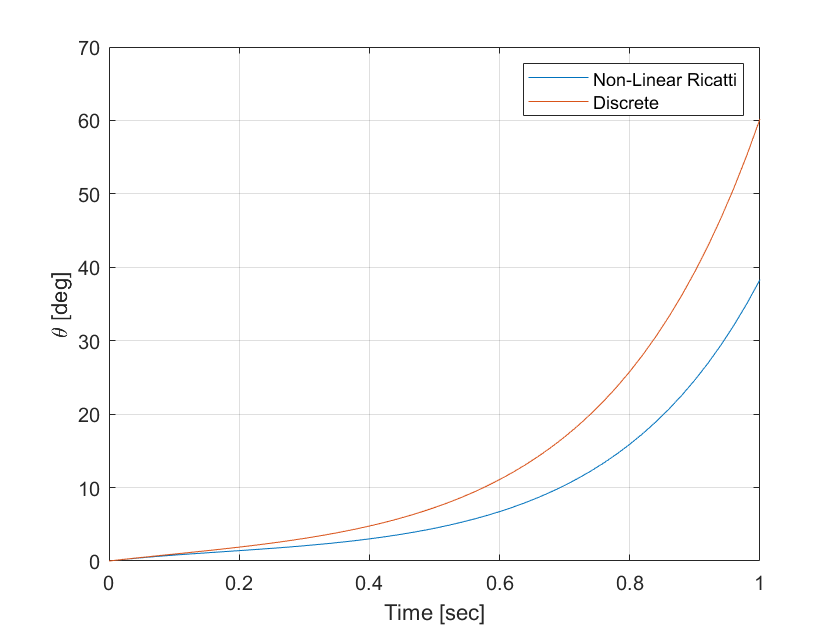

X_b1=X1;
U_b1=U1;
figure
plot(X_b.time,X_b.signals.values(:,1)*180/pi)
grid on
ylabel('{\theta} [deg]')
xlabel('Time [sec]')
hold on
plot((0:N)*dt,X1b)
legend('Non-Linear Ricatti','Discrete')

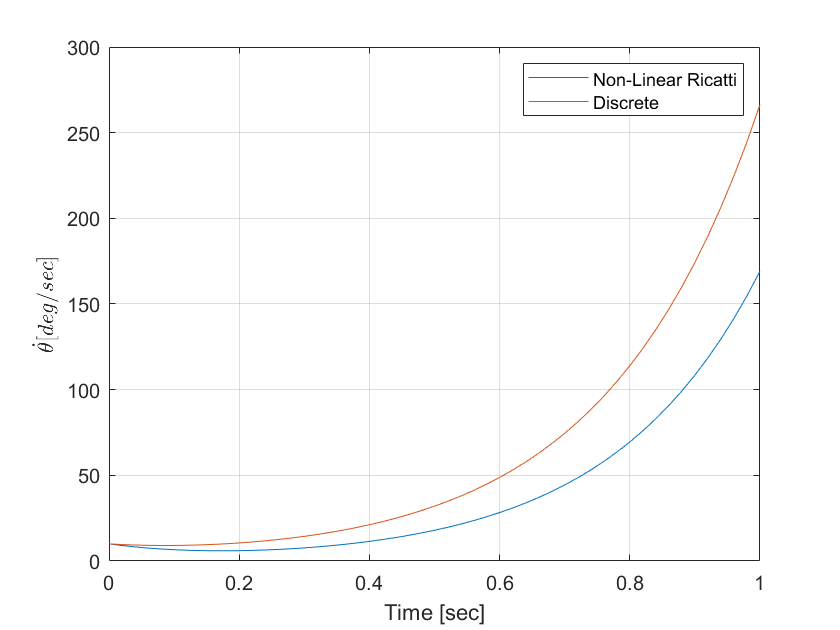


figure
plot(X_b.time,X_b.signals.values(:,2)*180/pi)
grid on
ylabel('$\dot{\theta } [deg/sec]$', 'Interpreter','latex')
xlabel('Time [sec]')
hold on
plot((0:N)*dt,X2b)
legend('Non-Linear Ricatti','Discrete')

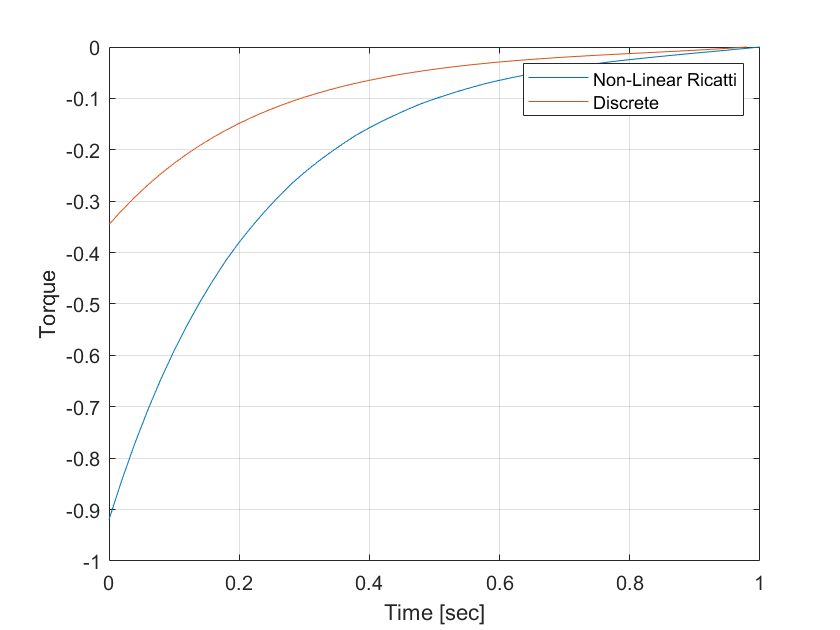

figure
plot(U_b.time,U_b.signals.values(:,1))
grid on
ylabel('Torque')
xlabel('Time [sec]')
hold on
plot((0:N-1)*dt,Ub)
legend('Non-Linear Ricatti','Discrete')